Hamming window function with respect to M=10


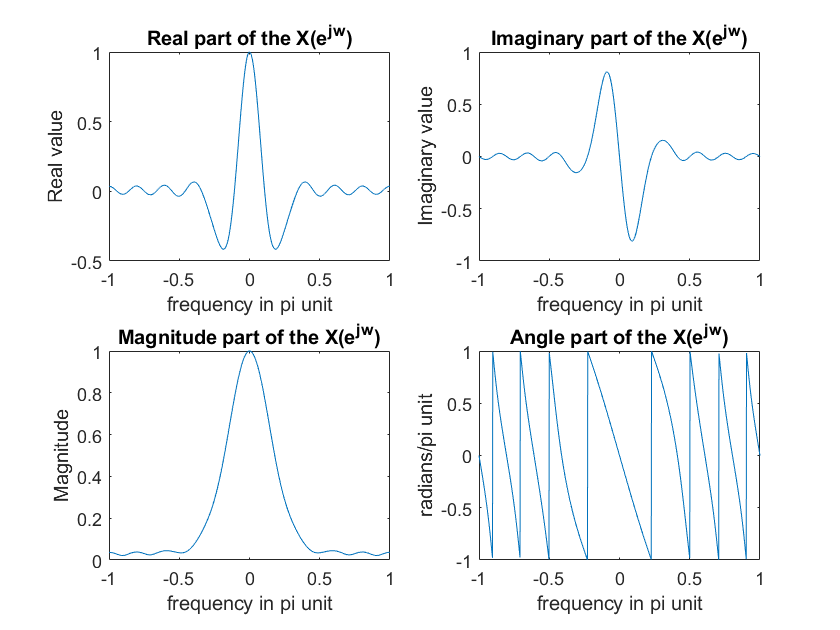

Hamming window function with respect to M=25


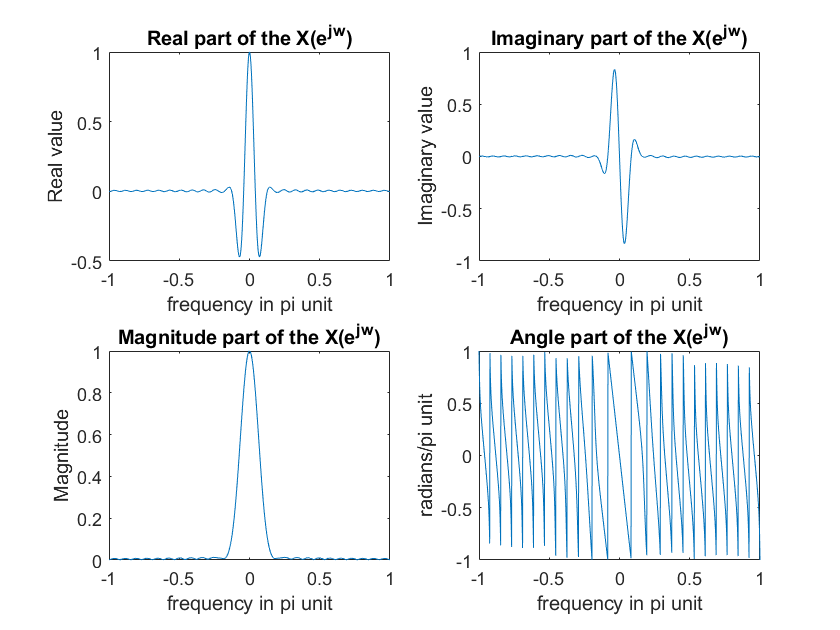

Hamming window function with respect to M=50


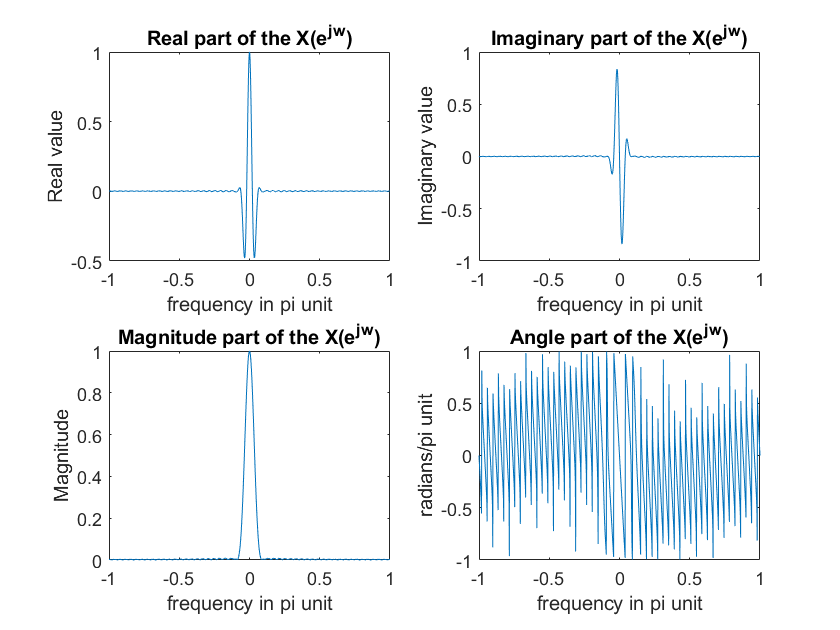

Hamming window function with respect to M=101


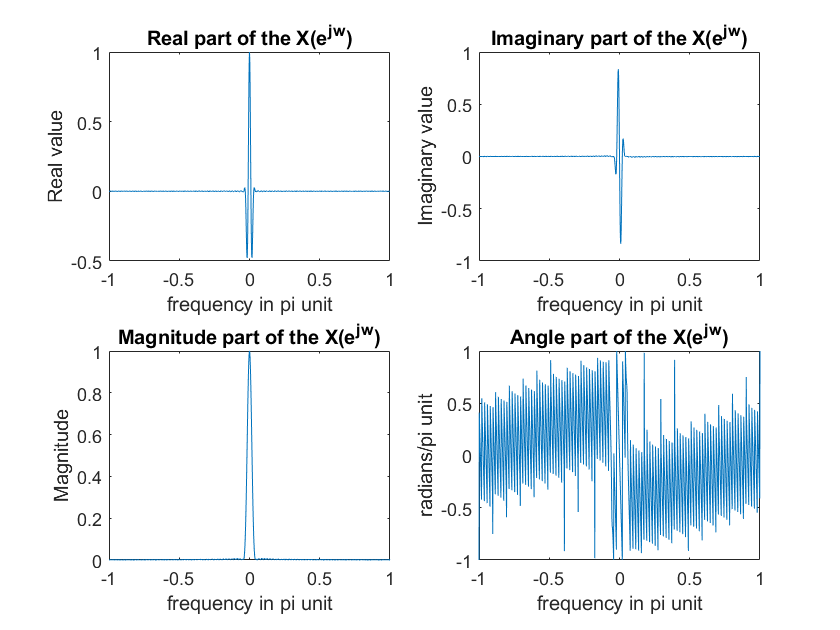

% Hamming Window
K=500;
k=-K:K;
w=(pi*k)/K;
M=[10 25 50 101];
for i=1:length(M)
    figure('Name',strcat('M=',num2str(M(i))))
    n=-50:M(i);
    ham=unitseq(min(n),M(i),0).*(0.54-0.46*cos(2*pi*n./(M(i)-1)));
    X=dtft(ham,n,w);
    disp(strcat('Hamming window function with respect to M=',num2str(M(i))))
    dfp4(X/max(X),w)
end